# Live testing script

clearvars

## Declare objects

### Initialise object properties

*Note: input ranges need to be double checked*

time_step = 0.5% seconds

time_step = 0.5000

simulation_time = 3600% seconds

simulation_time = 3600

simulation_time_hours = simulation_time / 3600 % 24h00 format

simulation_time_hours = 1

starting_time = 0% 24h00 format

starting_time = 0

starting_time = starting_time * 3600 % seconds 

starting_time = 0

arterial_SpO2 = 0.98 %

arterial_SpO2 = 0.9800

arterial_glucose =4% mmol/L

arterial_glucose = 4

arterial_insulin = 10% mU/L

arterial_insulin = 10

gut_SpO2 =0.4%

gut_SpO2 = 0.4000

gut_glucose = 5% mmol/L

gut_glucose = 5

gut_flowrate = 500% ml/min

gut_flowrate = 500

### Initialise objects

Gut = Gut(starting_time, time_step, gut_SpO2, gut_glucose, gut_flowrate)

Gut =   Gut with properties:

            time: 0
       time_step: 0.5000
        gut_SpO2: 0.4000
     gut_glucose: 5
    gut_flowrate: 500


### Create graphing storage vectors

time_vector = zeros(1,simulation_time/time_step);
arterial_SpO2_vector = zeros(1,simulation_time/time_step);
arterial_glucose_vector = zeros(1,simulation_time/time_step);
arterial_insulin_vector = zeros(1,simulation_time/time_step);
gut_SpO2_vector = zeros(1,simulation_time/time_step);
gut_glucose_vector = zeros(1,simulation_time/time_step);

## Run simulation

*Note: not currently doing anything, just a display of the code concept*

### Run loop

for i = 0:time_step:simulation_time-time_step
    % calculate new gut
    Gut = calc_gut(Gut, arterial_SpO2, arterial_glucose, arterial_insulin, gut_SpO2, gut_glucose, gut_flowrate);
    % create output vectors at each time step
    time_vector((i/time_step)+1) = Gut.time;
    arterial_SpO2_vector((i/time_step)+1) = arterial_SpO2;
    arterial_glucose_vector((i/time_step)+1) = arterial_glucose;
    arterial_insulin_vector((i/time_step)+1) = arterial_insulin;
    gut_SpO2_vector((i/time_step)+1) = Gut.gut_SpO2;
    gut_glucose_vector((i/time_step)+1) = Gut.gut_glucose;
end

### Output graphs

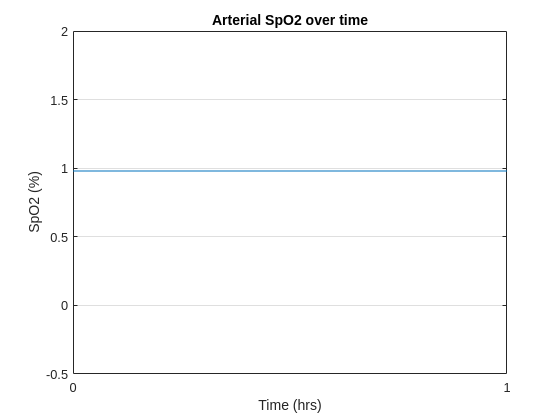

time_vector = time_vector / 3600; % convert to 24h00 format
% plotting arterial vectors
% arterial SpO2 plot
plot(time_vector,arterial_SpO2_vector)
title('Arterial SpO2 over time')
xlabel('Time (hrs)')
ylabel('SpO2 (%)')
grid on
xlim([0, simulation_time/3600])
xticks(0:1:simulation_time/3600)

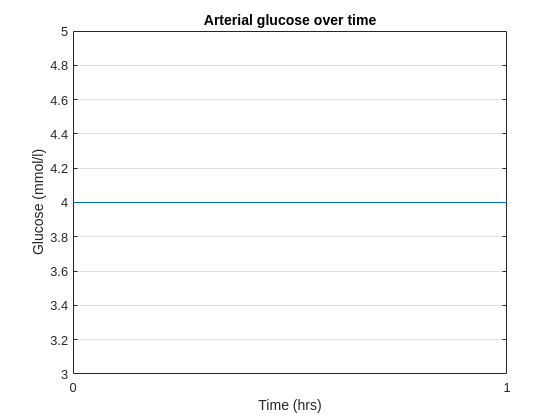

% arterial glucose plot
plot(time_vector,arterial_glucose_vector)
title('Arterial glucose over time')
xlabel('Time (hrs)')
ylabel('Glucose (mmol/l)')
grid on
xlim([0, simulation_time/3600])
xticks(0:1:simulation_time/3600)

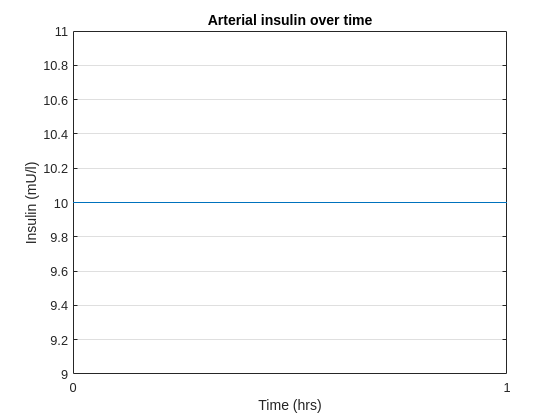

% arterial insulin plot
plot(time_vector,arterial_insulin_vector)
title('Arterial insulin over time')
xlabel('Time (hrs)')
ylabel('Insulin (mU/l)')
grid on
xlim([0, simulation_time/3600])
xticks(0:1:simulation_time/3600)

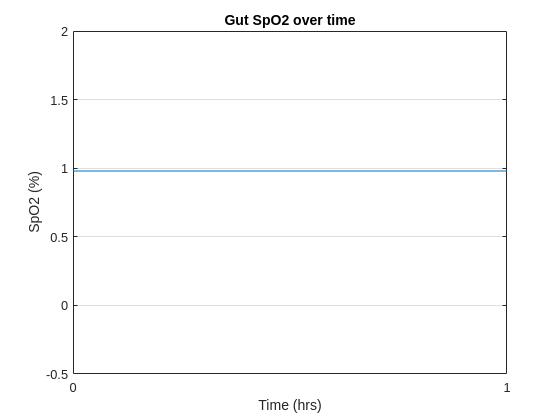

% plotting gut vectors
% gut SpO2 plot
plot(time_vector,gut_SpO2_vector)
title('Gut SpO2 over time')
xlabel('Time (hrs)')
ylabel('SpO2 (%)')
grid on
xlim([0, simulation_time/3600])
xticks(0:1:simulation_time/3600)

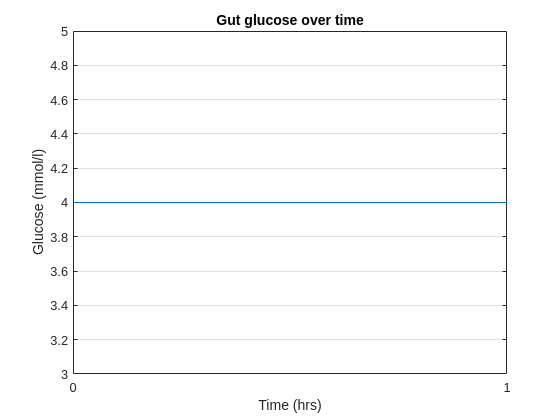

% gut glucose plot
plot(time_vector,gut_glucose_vector)
title('Gut glucose over time')
xlabel('Time (hrs)')
ylabel('Glucose (mmol/l)')
grid on
xlim([0, simulation_time/3600])
xticks(0:1:simulation_time/3600)

## Helper functions

### gut_calc

*returns new gut object, currently used in loop for visual ease, not much other use currently*

function new_Gut = calc_gut(Gut, arterial_SpO2, arterial_glucose, arterial_insulin, gut_SpO2, gut_glucose, gut_flowrate)
    Gut.time = Gut.time + Gut.time_step;
    Gut.gut_SpO2 = arterial_SpO2;
    Gut.gut_glucose = arterial_glucose;
    new_Gut = Gut;
end